## Loading the Data

The data can be loaded as follows.  The mat file is in the github directory

load roomPathData.mat

fc = pathData.fc; % Carrier frequency
i = 500;        % Choose RX
TX_x= pathData.txPos(1);
TX_y= pathData.txPos(2);% Tx location
RX_x = pathData.rxPos(i,1);
RX_y = pathData.rxPos(i,2);% Rx location
path_n = pathData.npaths(i); 
linkState = pathData.linkState(i);
pl = pathData.pl(i,:);
aoaAz = pathData.aoaAz(i,:)';
aoaEl = pathData.aoaEl(i,:)';
aodAz = pathData.aodAz(i,:)';
aodEl = pathData.aodEl(i,:)';
dly = pathData.dly(i,:);
pgain =pathData.gain(i,:)';



When you load the data you should see a structure, `pathData`.  In the data, there was a single TX and a large number of RX locations.  The configuration of the file is described in the following fields:

- `pathData.fc` :  The carrier frequency in Hz

- `pathData.txPos` :  The `(x,y)` position of the TX. 

- `pathData.posStep`:  The `(x,y)` grid spacing on which the RX locations were taken

The remaining fields are arrays with one row per RX location.  Some key fields are:

- `pathData.rxPos(i,:) : `The `(x,y)` position of the RX location `i`

- `pathData.npaths(i) : `The number of valid paths for RX location `i` .

- `pathData.linkState(i): 0=Outage = `No paths to this link, 1=LOS path, 2 = NLOS paths only.

For other fields, there is one column per path.  For position `i,` the paths will run from `j=1,...,npaths(i):  `

- `pathData.pl(i,j) : `The path loss on path `j` for RX location `i` .

- `pathData.aoaAz(i,j), aoaEl(i,j) : `The azimuth and elevation angle of arrival of path `j` for RX location `i` .

- `pathData.aodAz(i,j), aodEl(i,j) : `The azimuth and elevation angle of departure of  path `j` for RX location `i` .

As an example, we can print the total area:

minPos = min(pathData.rxPos);
maxPos = max(pathData.rxPos);
posArea = maxPos - minPos;

fprintf('The area is %7.2f m x %7.2f m\n', posArea(1), posArea(2));

The area is   14.25 m x   16.65 m


We can also print the number of RX locations and fraction in each link state.

nrxPos = size(pathData.rxPos, 1);


fprintf(1,'Number of RX locations = %d\n', nrxPos);

Number of RX locations = 5071




for i = 1:length(pathData.linkStateLabel)
    p = mean(pathData.linkState == i-1);
    fprintf(1,'Fraction %10s = %7.5f\n', pathData.linkStateLabel{i}, p);
end

Fraction     Outage = 0.04969
Fraction        LOS = 0.67127
Fraction       NLOS = 0.27904


## Visualizing the LOS state

To help visualize the data, I have created a simple class, `DataMapper`.  You create the object with the positions on which the values will be mapped.  In this case, the positions are `rxPos`.   You also provide the grid spacing.

rxPos = pathData.rxPos;
mapper = DataMapper(rxPos, pathData.posStep);

Once you have created the `mapper` object, you can give it any values to plot. For example, suppose we plot the link state. The link states have values 0,1,2.  We will add a value of `noVal = 3` for positions on which data is not provided.

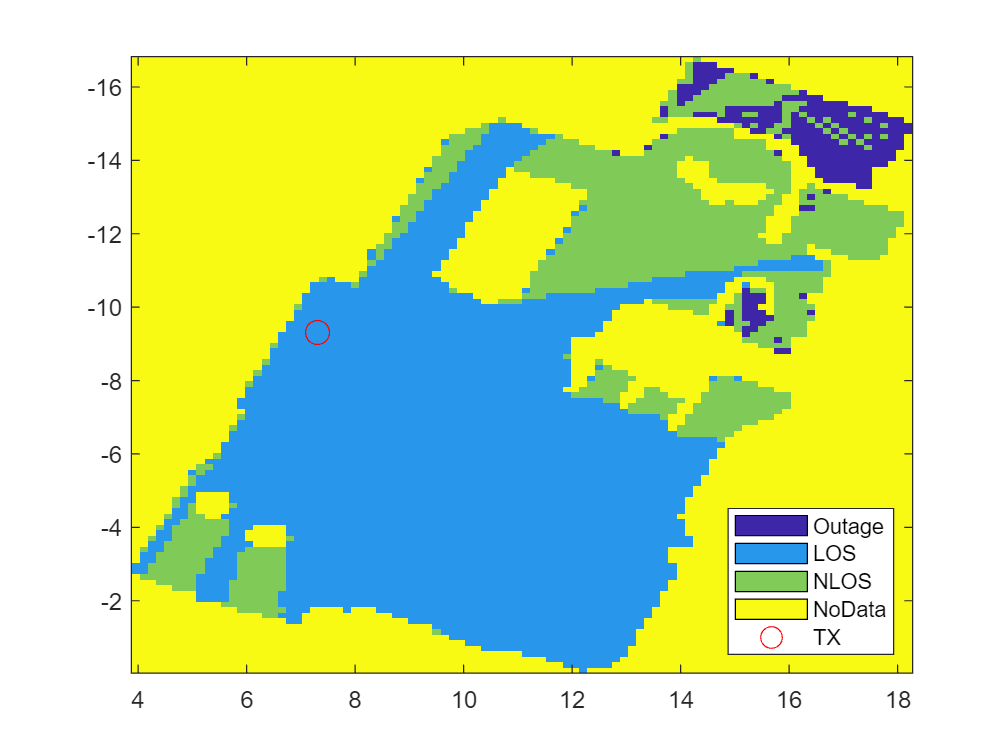


clf;
noDataValue = 3;  % Use this value for positions with no data

% Legend labels
legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

% Overlay the TX position
txPos = pathData.txPos;
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'TX');
hold off;

% Display the legend
legend('Location', 'SouthEast');

## Plotting the RX power and SNR

As another plotting example, we can compute the total RX power by  summing the power from each path.  This is the power that would be received with omni-directional TX and RX.

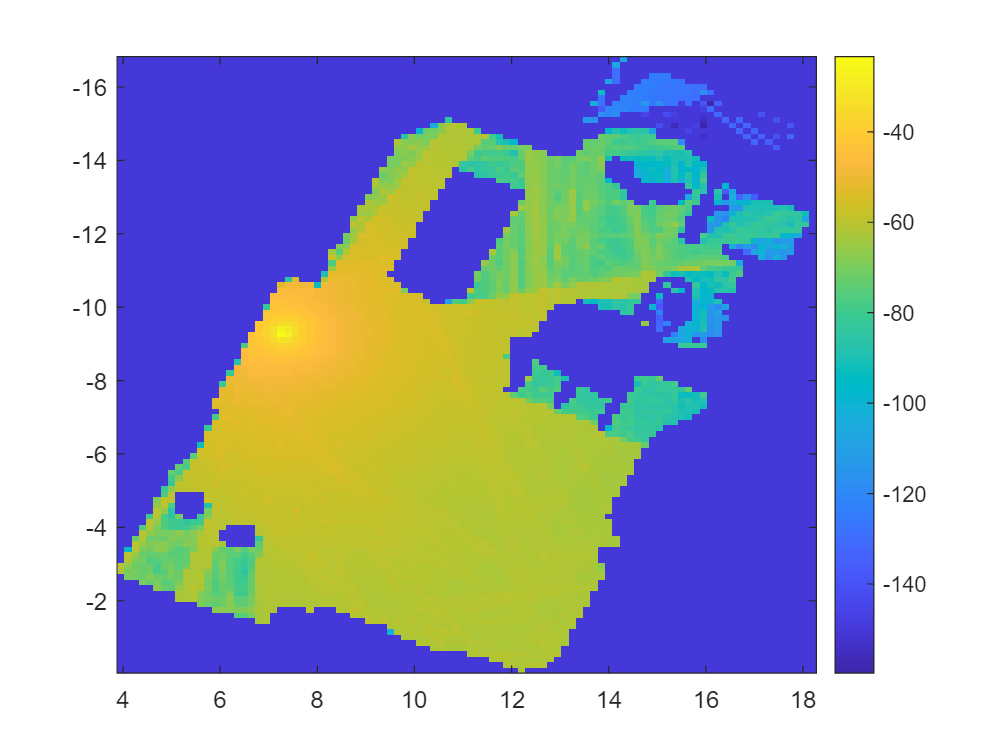


txPow = 15;  % TX power in dBm

% Get the path loss data
plos = pathData.pl;
nlinks = size(plos,1);

% Initialize locations to a minimum power
rxPowMin = -150;
rxPow = repmat(rxPowMin, nlinks,1);

% Loop over the locations and compute the RX power
for i = 1:nlinks
    k = pathData.npaths(i); 
    if k >  0
        rxPow(i) = txPow + pow2db(sum(db2pow(-plos(i,1:k))));
    end
end

% Plot the results
mapper.plot(rxPow, 'noDataValue', rxPowMin);
colorbar();

We could also plot the SNR with omni antennas.

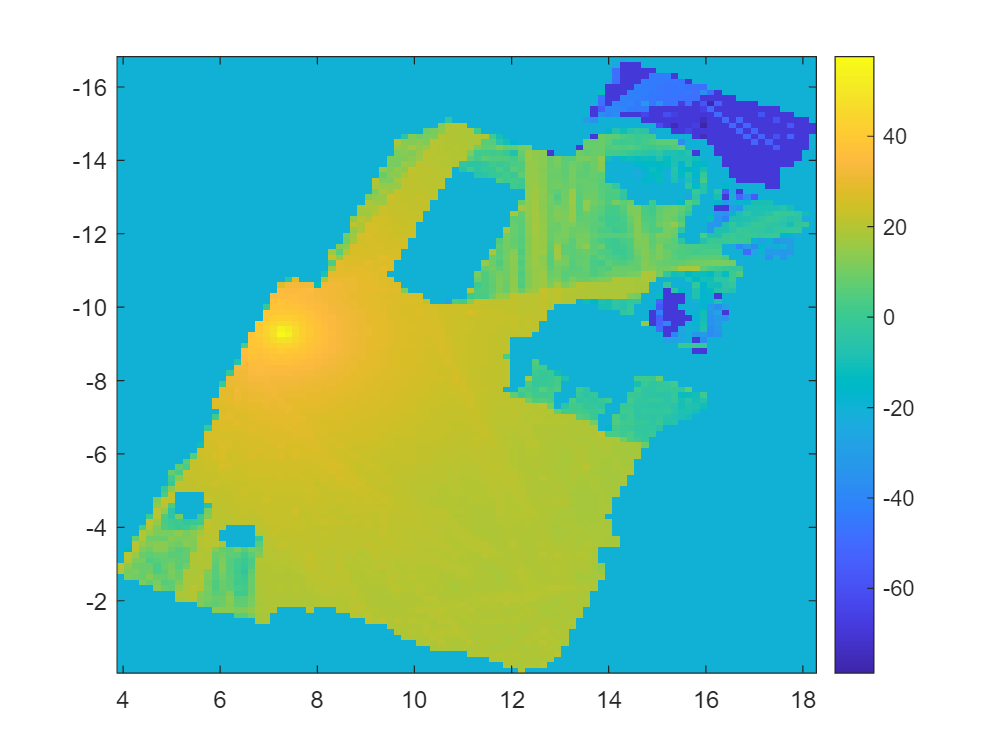

nf = 7;      % Noise figure
bw = 400e6;  % Bandwidth
Ekt = -174;  % Theremal noise

% SNR
snr = rxPow - nf - Ekt - 10*log10(bw);

% Plot the results
snrMin = -20;
mapper.plot(snr, 'noDataValue', snrMin);
colorbar();

%Antenna
fc = pathData.fc ;  % Carrier frequency
elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis = [0,1,0];

%Antenna Arrays
nantgNB = [4,4];
nantUE = [2,2];

% TODO:  Construct a URA
%   arrgNB = phased.URA(...);
%   arrUE = phased.URA(...);
lambda = physconst('Lightspeed') / fc;
dsep = 0.5*lambda;
arrgNB = phased.URA(nantgNB,dsep,'ArrayNormal','x');
arrUE  = phased.URA(nantUE,dsep,'ArrayNormal','x');

%Array Platform
arrPlatformgNB = ArrayPlatform('elem', elem, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', elem, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

%rotote the UE to an angle of 135 degrees which is close to the main angle of arrival. 
%azUE = 135;
%elUE = -10;
%arrPlatformUE.alignAxes(azUE, elUE);
%[svTx, elemGainTx] = arrPlatformgNB(aodAz, aodEl);
%[svRx, elemGainRx] = arrPlatformUE(aoaAz, aoaEl);
%gainElem = pgain + elemGainTx + elemGainRx;

Find the angle with maximum gain

azUE = -180:10:180;
elUE = -90:10:90;
gain = zeros(length(azUE),length(elUE));
for i =1:length(azUE)
    for j = 1:length(elUE)
        arrPlatformUE.alignAxes(azUE(i), elUE(j));
        [svTx, elemGainTx] = arrPlatformgNB(aodAz, aodEl);
        [svRx, elemGainRx] = arrPlatformUE(aoaAz, aoaEl);
        gainElem = pgain + elemGainTx + elemGainRx;
        gain(i,j) = sum(db2mag( gainElem));
    end
end

[maxgain, i] = max(gain(:));
[x, y]=find(gain==maxgain);
azUE0 = azUE(x);
elUE0 = elUE(y);
arrPlatformUE.release();
arrPlatformUE.alignAxes(azUE0, elUE0);
[svTx, elemGainTx] = arrPlatformgNB(aodAz, aodEl);
[svRx, elemGainRx] = arrPlatformUE(aoaAz, aoaEl);
gainElem = pgain + elemGainTx + elemGainRx;

%OFDM Channel
SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Enoise = -50;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', pgain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);

frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

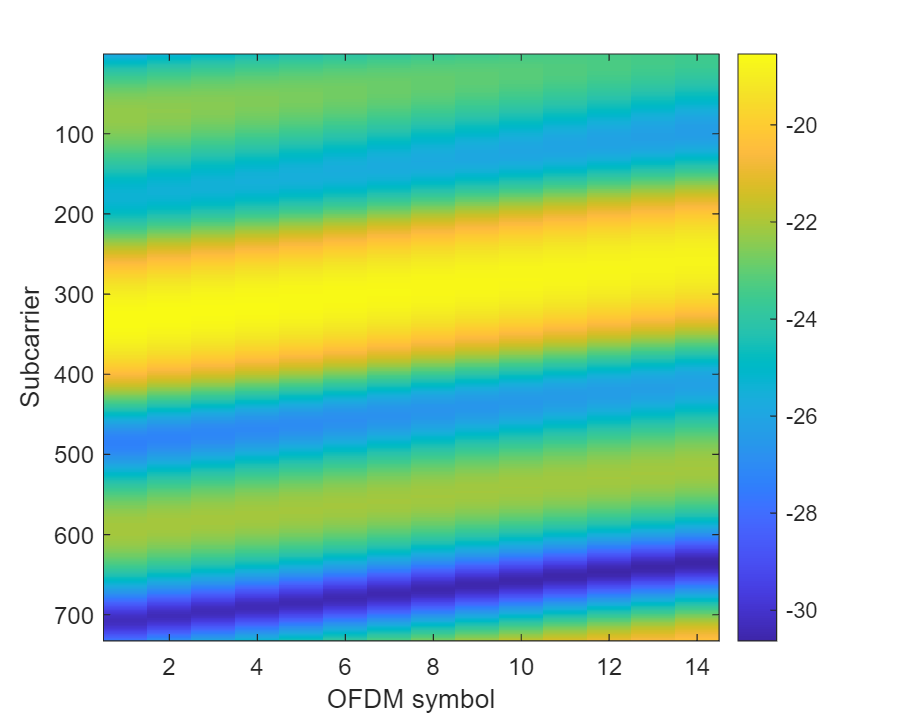


%
clf;
set(gcf,'Position', [0,0,500,400]);
chanGainSing = squeeze( abs(chanGrid(3,4,:,:)).^2 );
snrSing = 10*log10(chanGainSing / noiseVar);
imagesc(snrSing);
colorbar();
xlabel('OFDM symbol');
ylabel('Subcarrier');


% Configuring the DM-RS and PDSCH
dmrsConfig = nrPDSCHDMRSConfig(...
    'NumCDMGroupsWithoutData', 1, ...  % No unused DM-RS
    'DMRSAdditionalPosition', 1, ...   % Number additional DM-RS in time
    'DMRSConfigurationType', 2);       % 1=6 DM-RS per sym,  2=4 per sym

% Configure the physical downlink shared channel parameters
pdschConfig = nrPDSCHConfig();
pdschConfig.NSizeBWP = [];   % Empty implies that the value is equal to NSizeGrid
pdschConfig.NStartBWP = [];  % Empty implies that the value is equal to NStartGrid
pdschConfig.PRBSet = (0:NRB-1);   % Allocate the complete carrier
pdschConfig.SymbolAllocation = [0 14]; % Symbol allocation [S L]
pdschConfig.MappingType = 'A'; % PDSCH mapping type ('A' or 'B')
pdschConfig.EnablePTRS = true;
pdschConfig.PTRS =  nrPDSCHPTRSConfig();
pdschConfig.DMRS = dmrsConfig;

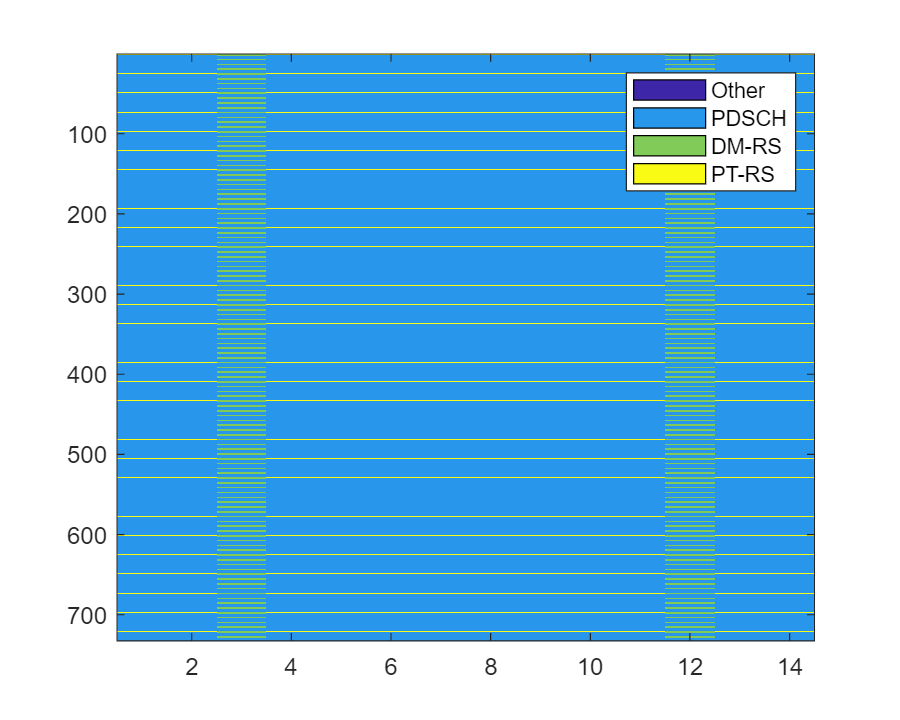

tx = NRgNBTxFD(carrierConfig, pdschConfig);
tx.step();
plotChan(tx.txGridChan, tx.chanNames);

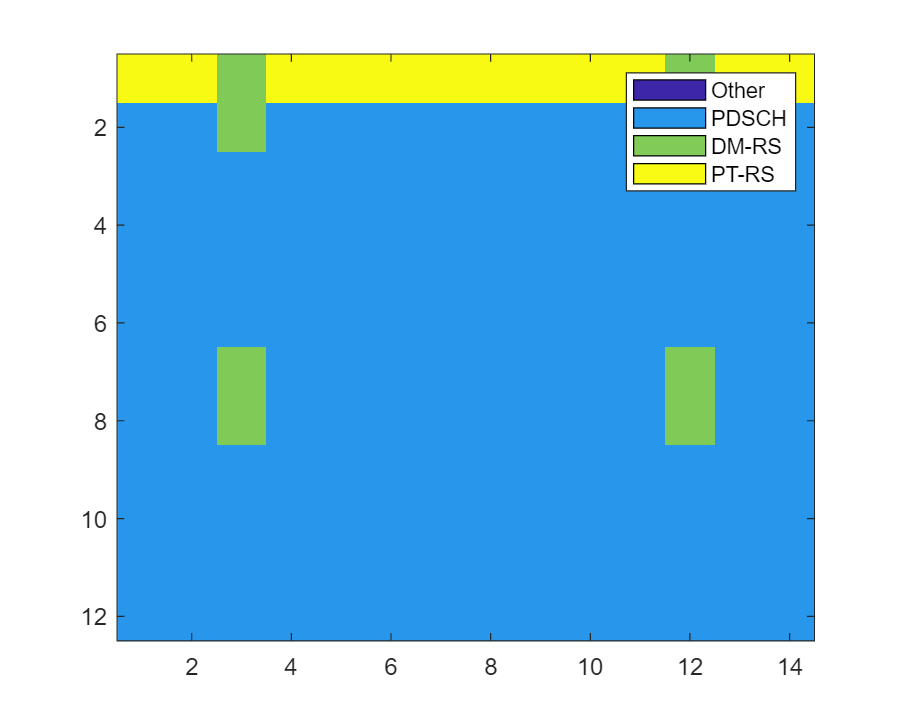

plotChan(tx.txGridChan(1:nscPerRB,:), tx.chanNames);

nchan = length(tx.chanNames);
for i=1:nchan
    p = mean(tx.txGridChan == i-1,'all');
    fprintf('Channel: %-7s:  %7.3f\n', tx.chanNames{i}, p);
end

Channel: Other  :    0.000
Channel: PDSCH  :    0.916
Channel: DM-RS  :    0.048
Channel: PT-RS  :    0.036


% Create TX and RX
tx = NRgNBTxFD(carrierConfig, pdschConfig);
rx = NRUERxFD(carrierConfig, pdschConfig);

% Run the TX
txGrid = tx.step();

% Run the channel
frameNum = 0;
slotNum = 0;
rxGrid = zeros(4,16,732,14);
%[a,b,c,d] = size(chanGrid);
for i = 1:4
    for j = 1:16
        rxGrid(i,j,:,:) = squeeze(chanGrid(i,j,:,:)).*txGrid;
    end
end

txBits0 = qamdemod(txGrid, 4, 'OutputType', 'bit',...
                'UnitAveragePower', true);
%reshape(txBits0,18776,1);

% estimator
chanEstGrid = zeros(size(chanGrid));
for i = 1:4
    for j =1:16
        rx.chanEst(squeeze(rxGrid(i,j,:,:)));
        chanEstGrid(i,j,:,:) = rx.chanEstGrid;
    end
end

size(rxGrid)

ans =      4    16   732    14


% Equalization

llr = zeros(4,16,18776);
SymEq= zeros(4,16,9388);
for i = 1:4
    for j =1:16
        pdschInd = nrPDSCHIndices(carrierConfig, pdschConfig);
        rxGrid1 = squeeze(rxGrid(i,j,:,:));
        chanGrid1 = squeeze(chanGrid(i,j,:,:));
        pdschSym = rxGrid(pdschInd);
        pdschChan = chanGrid1(pdschInd);
        pdschSymEq = conj(pdschChan).*pdschSym./...
                (abs(pdschChan).^2 + noiseEst);
        SymEq(i,j,:) =  pdschSymEq;  
        bitsPerSym = 2;
        M = 2^bitsPerSym;
        rxBits = qamdemod(pdschSymEq, M, 'OutputType', 'bit',...
                'UnitAveragePower', true);
        llr(i,j,:) = rxBits;
    end
end

%rx.chanEst(rxGrid);
%rxBits = rx.step(rxGrid);